%%% READ ME %%%
% Scriptet virker kun på Matlab 2020 og nyere
% Legg ActualSpeedrun mappen i C:\Users\Username\Documents\MATLAB
% VIEW -> HIDE CODE (for beste visning

addpath('ActualSpeedrun/Funksjoner/') % Legger til folder med funksjoner til matlab path
addpath('ActualSpeedrun/Images') % Legger til folder med bilder i matlab path

clearvars
clf

# Club Cartesian

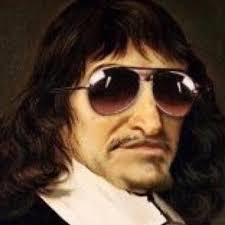



syms y(x)

y(x) = x^2+2*x-2;
xFrom =-2;
xTo = 2;
xAxisDensity = 0.5;
yAxisDensity = 0.5;
yOfEquals = 0.4;
chooseTable = false;
choosePlot = true;
chooseXAxisDensity = true;
chooseYAxisDensity = false;
disp(func2link(y(x)))

<a href="https://www.wolframalpha.com/input/?i=2*x%2Bx%5E2-2">Vis funksjon i wolfram</a>


%%%% MAKE TABLE %%%%
stringSymFunc = "y(" + string(yOfEquals) + ") symb:";
stringDoubleFunc = "y(" + string(yOfEquals) + ") double:";
yAnswer = string(y(yOfEquals));
yAnswerDouble = double(y(yOfEquals));

%vis yOfEqualsvalue i celle til venstre

Query = {stringSymFunc;stringDoubleFunc};
Answer = [yAnswer; yAnswerDouble ];

T = table(Query, Answer);
disp(T)

           Query             Answer 
    ____________________    ________

    {["y(0.4) symb:"  ]}    "-26/25"
    {["y(0.4) double:"]}    "-1.04" 



doubleXFrom = double(xFrom);
doubleXTo = double(xTo);
funcSpan = doubleXFrom-doubleXTo;
V=zeros(funcSpan, 2); %preallocating matrix


%%%% MAKE ARRAY %%%%
absXFrom = abs(xFrom);

a = 0;
if chooseXAxisDensity == 1
    for n = xFrom:xAxisDensity:xTo
        a= a+1;
    V(a,1) = n;
    V(a,2) = y(n);
    end
else
    for n = xFrom:xTo
        a= a+1;
    V(a,1) = n;
    V(a,2) = y(n);
    end
end


%%% FIND ARRAY PROPERTIES %%%%

% Find max and min values
minV = min(V);
minV = round(minV(2));
maxV = max(V);
maxV = round(maxV(2));

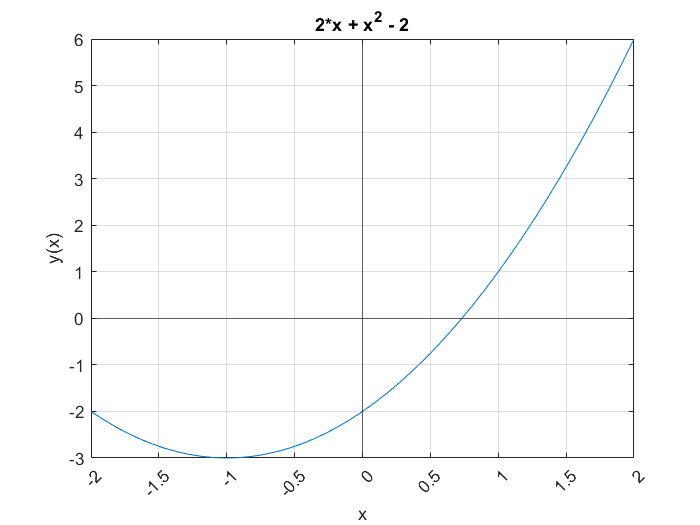


%%%% PLOT %%%%
if choosePlot == 1
    firstValue = double(y(xFrom));
    lastValue = double(y(xTo));
    fplot(y,[xFrom xTo])
    xlim([xFrom xTo])
    yline(0);
    xline(0);
    if chooseXAxisDensity == 1
        xticks(xFrom:xAxisDensity:xTo)    
    end
    
    if chooseYAxisDensity == 1
        yticks(minV:yAxisDensity:maxV)    
    end
    
    
    xtickangle(45)
    ylabel('y(x)')
    xlabel('x')
    title(string(y))
    grid on
end


%%%% MAKE AND DISPLAY TABLE %%%%
if chooseTable == 1
    calculateTable = array2table(V,"VariableNames",{'x', 'y(x)'});
    disp(calculateTable);
end